%% =========================================================
%  MULTI-GROUP COMPARISON VS LESION
%
%  Groups:
%   - Spike
%   - Spike + HFO
%   - HFO
%
%  Reference:
%   - Lesion scout (mask)
%
%  INPUTS:
%   - Cortex surface exported from Brainstorm
%   - Scout lesion exported separately
%   - Scout spike exported separately
%   - Scout spikeHFO exported separately
%   - Scout HFO exported separately
%
%  OUTPUT:
%   - Numerical metrics per group
%   - Summary plots with all groups together
%   - One 3D figure per group
%% =========================================================

clear; clc; close all;

%% =========================
% 1) FILES: EDIT THESE PATHS
%% =========================

cortex_file    = 'C:\Users\prego\Documents\brainstorm_db\ESI_10-10_12-03-2026_EBO\anat\EBO\tess_cortex_pial_low.mat';

mask_file      = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO\scout_lesion_mask.mat';
spike_file     = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO\scout_lesion_spike.mat';
spikeHFO_file  = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO\scout_lesion_spikeHFO.mat';
HFO_file       = 'C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO\scout_lesion_HFO.mat';

% Brainstorm usually stores vertices in meters
% Use 1000 to convert to mm
unit_scale = 1000;


%% =========================
% 2) LOAD DATA
%% =========================

sCortex  = load(cortex_file);
mask     = load(mask_file);
spike    = load(spike_file);
spikeHFO = load(spikeHFO_file);
HFO      = load(HFO_file);

% --- Cortex vertices ---
if isfield(sCortex, 'Vertices')
    Vertices = sCortex.Vertices;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Vertices')
    Vertices = sCortex.sSurf.Vertices;
else
    error('No se ha encontrado el campo Vertices en el archivo del cortex.');
end

% --- Cortex faces (optional, for visualization) ---
Faces = [];
if isfield(sCortex, 'Faces')
    Faces = sCortex.Faces;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Faces')
    Faces = sCortex.sSurf.Faces;
end

Vertices = Vertices * unit_scale;


%% =========================
% 3) EXTRACT SCOUT VERTICES
%% =========================

lesion_vertices   = get_first_scout_vertices(mask, 'mask');
spike_vertices    = get_first_scout_vertices(spike, 'spike');
spikeHFO_vertices = get_first_scout_vertices(spikeHFO, 'spikeHFO');
HFO_vertices      = get_first_scout_vertices(HFO, 'HFO');

lesion_coords   = Vertices(lesion_vertices, :);
spike_coords    = Vertices(spike_vertices, :);
spikeHFO_coords = Vertices(spikeHFO_vertices, :);
HFO_coords      = Vertices(HFO_vertices, :);


%% =========================
% 4) DEFINE GROUPS
%% =========================

group_names = {'Spike', 'Spike+HFO', 'HFO'};
group_vertices = {spike_vertices, spikeHFO_vertices, HFO_vertices};
group_coords   = {spike_coords, spikeHFO_coords, HFO_coords};

nGroups = length(group_names);

% Colors for plots
group_colors = [
    0.20 0.45 0.85   % blue
    0.85 0.40 0.20   % orange/red
    0.25 0.65 0.35   % green
    ];

% Containers
all_min_distances   = zeros(1, nGroups);
all_mean_distances  = zeros(1, nGroups);
all_median_distances = zeros(1, nGroups);
all_spatial_disp    = zeros(1, nGroups);
all_std_distances   = zeros(1, nGroups);
all_vertex_distances = cell(1, nGroups);


%% =========================
% 5) COMPUTE DISTANCES FOR EACH GROUP
%% =========================

for g = 1:nGroups
    current_coords = group_coords{g};

    % Pairwise distances: each group vertex to each lesion vertex
    D = pdist2(current_coords, lesion_coords);

    % For each group vertex, minimum distance to lesion
    d_vertex_to_lesion = min(D, [], 2);

    all_vertex_distances{g} = d_vertex_to_lesion;

    % Metrics
    all_min_distances(g)    = min(d_vertex_to_lesion);
    all_mean_distances(g)   = mean(d_vertex_to_lesion);
    all_median_distances(g) = median(d_vertex_to_lesion);

    % Spatial dispersion (RMS)
    all_spatial_disp(g) = sqrt(mean(d_vertex_to_lesion.^2));

    % Standard deviation of vertex-wise distances
    all_std_distances(g) = std(d_vertex_to_lesion);
end


%% =========================
% 6) RESULTS TABLE
%% =========================

ResultsTable = table( ...
    group_names', ...
    cellfun(@length, group_vertices)', ...
    all_min_distances', ...
    all_mean_distances', ...
    all_median_distances', ...
    all_spatial_disp', ...
    all_std_distances', ...
    'VariableNames', { ...
        'Group', ...
        'NumVertices', ...
        'MinDistance_mm', ...
        'MeanDistance_mm', ...
        'MedianDistance_mm', ...
        'SpatialDispersion_RMS_mm', ...
        'StdDistance_mm'} ...
    );

disp('==========================================');

disp('RESULTS TABLE');

RESULTS TABLE


disp('==========================================');

disp(ResultsTable);

        Group        NumVertices    MinDistance_mm    MeanDistance_mm    MedianDistance_mm    SpatialDispersion_RMS_mm    StdDistance_mm
    _____________    ___________    ______________    _______________    _________________    ________________________    ______________

    {'Spike'    }        103            9.0005            27.975              29.486                   29.102                 8.0615    
    {'Spike+HFO'}         34            18.964             29.56              29.979                   29.868                 4.3433    
    {'HFO'      }         75                 0            12.011              10.384                   13.623                 6.4722    



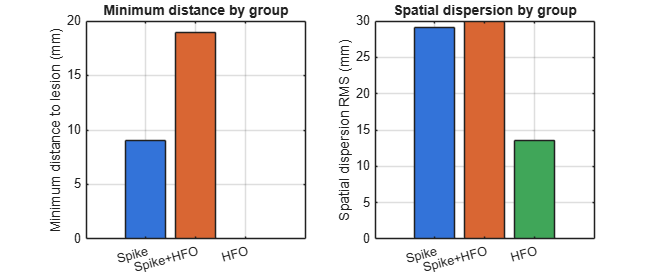

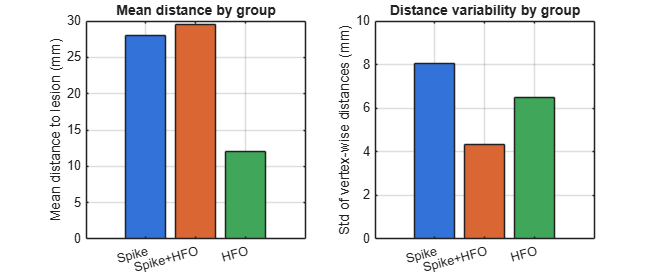

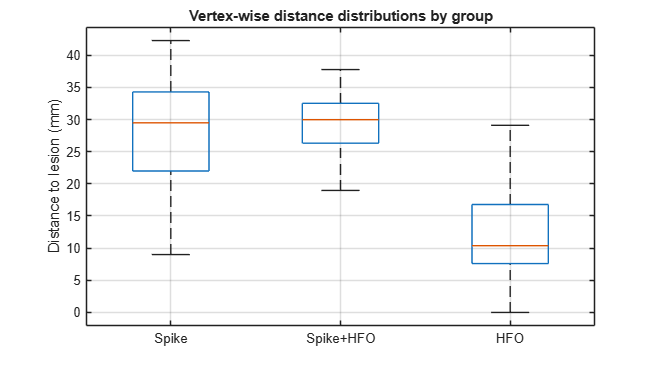

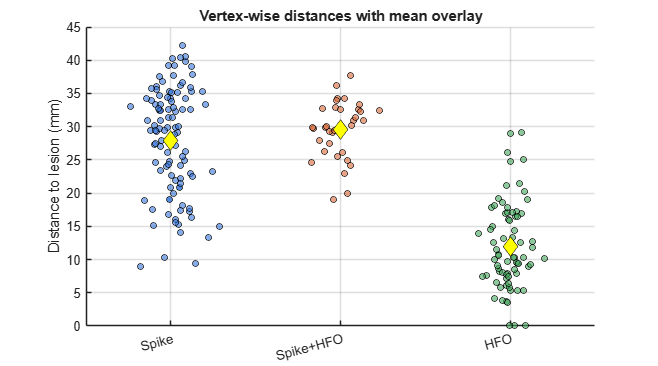

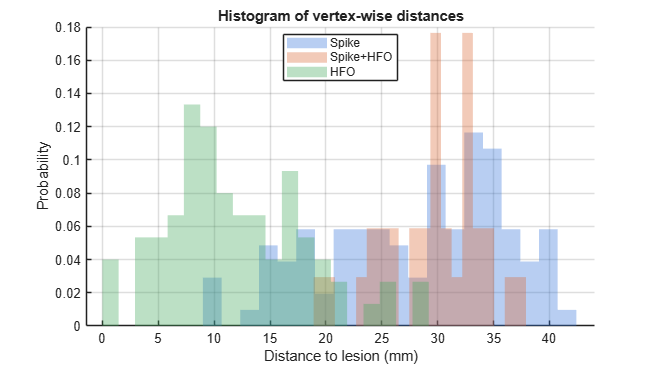

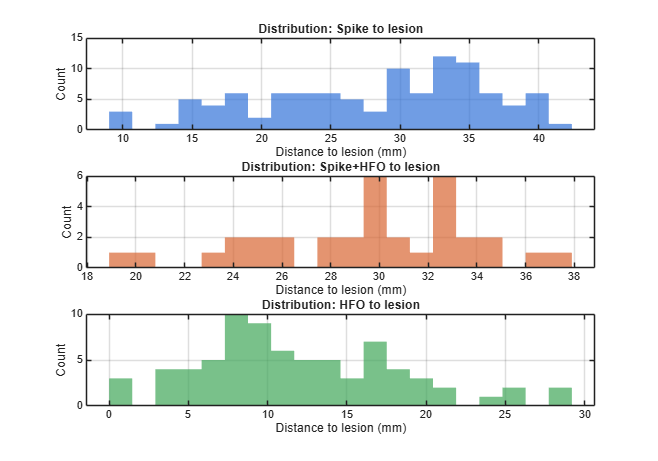

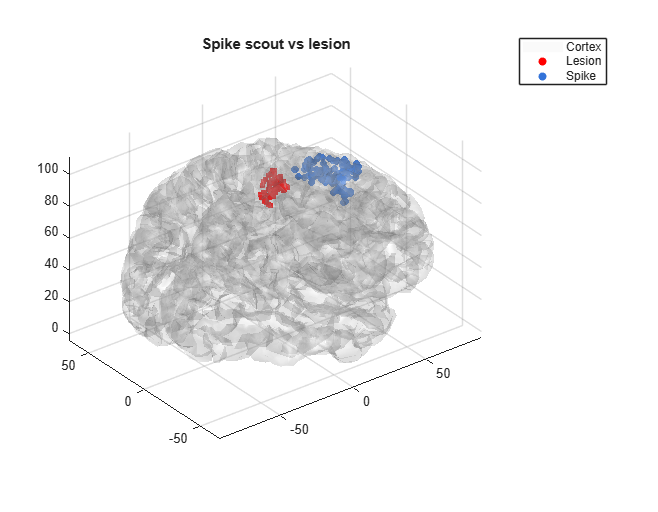

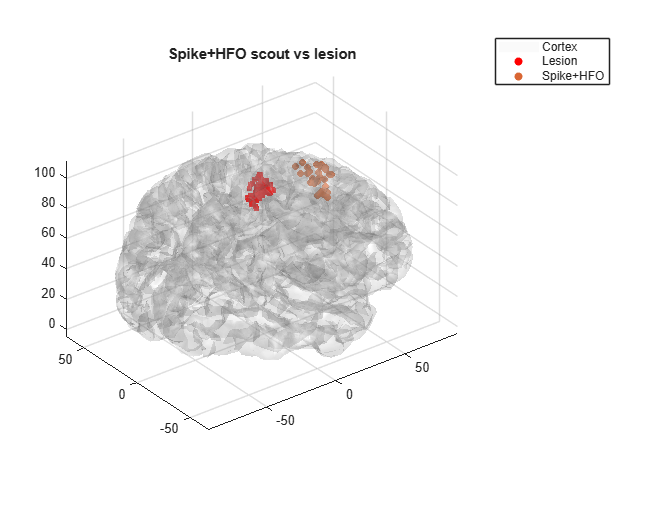



%% =========================
% 7) SUMMARY BAR PLOTS
%% =========================

figure('Color','w','Position',[100 100 1200 500]);

subplot(1,2,1);
b1 = bar(all_min_distances, 'FaceColor', 'flat');
for i = 1:nGroups
    b1.CData(i,:) = group_colors(i,:);
end
set(gca, 'XTick', 1:nGroups, 'XTickLabel', group_names, 'XTickLabelRotation', 15);
ylabel('Minimum distance to lesion (mm)');
title('Minimum distance by group');
grid on;

subplot(1,2,2);
b2 = bar(all_spatial_disp, 'FaceColor', 'flat');
for i = 1:nGroups
    b2.CData(i,:) = group_colors(i,:);
end
set(gca, 'XTick', 1:nGroups, 'XTickLabel', group_names, 'XTickLabelRotation', 15);
ylabel('Spatial dispersion RMS (mm)');
title('Spatial dispersion by group');
grid on;


%% =========================
% 8) SECOND SUMMARY FIGURE
%% =========================

figure('Color','w','Position',[120 120 1200 500]);

subplot(1,2,1);
b3 = bar(all_mean_distances, 'FaceColor', 'flat');
for i = 1:nGroups
    b3.CData(i,:) = group_colors(i,:);
end
set(gca, 'XTick', 1:nGroups, 'XTickLabel', group_names, 'XTickLabelRotation', 15);
ylabel('Mean distance to lesion (mm)');
title('Mean distance by group');
grid on;

subplot(1,2,2);
b4 = bar(all_std_distances, 'FaceColor', 'flat');
for i = 1:nGroups
    b4.CData(i,:) = group_colors(i,:);
end
set(gca, 'XTick', 1:nGroups, 'XTickLabel', group_names, 'XTickLabelRotation', 15);
ylabel('Std of vertex-wise distances (mm)');
title('Distance variability by group');
grid on;


%% =========================
% 9) BOXPLOT WITH ALL GROUPS TOGETHER
%% =========================

all_distances_concat = [];
group_labels_concat = {};

for g = 1:nGroups
    d = all_vertex_distances{g};
    all_distances_concat = [all_distances_concat; d(:)]; %#ok<AGROW>
    group_labels_concat = [group_labels_concat; repmat(group_names(g), length(d), 1)]; %#ok<AGROW>
end

figure('Color','w','Position',[140 140 900 500]);
boxplot(all_distances_concat, group_labels_concat, 'Symbol', 'k+');
ylabel('Distance to lesion (mm)');
title('Vertex-wise distance distributions by group');
grid on;


%% =========================
% 10) SCATTER + MEAN OVERLAY
%% =========================

figure('Color','w','Position',[160 160 900 500]);
hold on;

for g = 1:nGroups
    xvals = g + 0.08 * randn(size(all_vertex_distances{g}));
    scatter(xvals, all_vertex_distances{g}, 20, ...
        'MarkerFaceColor', group_colors(g,:), ...
        'MarkerEdgeColor', 'k', ...
        'MarkerFaceAlpha', 0.6);
    
    plot(g, mean(all_vertex_distances{g}), 'kd', ...
        'MarkerFaceColor', 'y', 'MarkerSize', 10);
end

set(gca, 'XTick', 1:nGroups, 'XTickLabel', group_names, 'XTickLabelRotation', 15);
ylabel('Distance to lesion (mm)');
title('Vertex-wise distances with mean overlay');
grid on;
hold off;


%% =========================
% 11) HISTOGRAMS OVERLAID
%% =========================

figure('Color','w','Position',[180 180 900 500]);
hold on;

for g = 1:nGroups
    histogram(all_vertex_distances{g}, 20, ...
        'Normalization', 'probability', ...
        'FaceColor', group_colors(g,:), ...
        'FaceAlpha', 0.35, ...
        'EdgeColor', 'none');
end

xlabel('Distance to lesion (mm)');
ylabel('Probability');
title('Histogram of vertex-wise distances');
legend(group_names, 'Location', 'best');
grid on;
hold off;


%% =========================
% 12) OPTIONAL RAINCLOUD-STYLE / FALLBACK
%% =========================

figure('Color','w','Position',[200 200 1000 700]);

if exist('raincloud_plot','file') == 2
    for g = 1:nGroups
        subplot(nGroups,1,g);
        raincloud_plot(all_vertex_distances{g}(:), ...
            'box_on', 1, ...
            'color', group_colors(g,:), ...
            'bandwidth', .2, ...
            'density_type', 'ks');
        title(['Raincloud Plot: ' group_names{g} ' to lesion']);
        xlabel('Distance to lesion (mm)');
        box off;
    end
else
    for g = 1:nGroups
        subplot(nGroups,1,g);
        histogram(all_vertex_distances{g}, 20, ...
            'FaceColor', group_colors(g,:), ...
            'EdgeColor', 'none', ...
            'FaceAlpha', 0.7);
        xlabel('Distance to lesion (mm)');
        ylabel('Count');
        title(['Distribution: ' group_names{g} ' to lesion']);
        grid on;
    end
end


%% =========================
% 13) 3D VISUALIZATION - ONE FIGURE PER GROUP
%% =========================

for g = 1:nGroups
    figure('Color','w','Position',[220+40*g 220+40*g 900 700]);

    if ~isempty(Faces)
        trisurf(Faces, Vertices(:,1), Vertices(:,2), Vertices(:,3), ...
            'FaceColor', [0.85 0.85 0.85], ...
            'EdgeColor', 'none', ...
            'FaceAlpha', 0.12);
        axis equal; hold on;
        lighting gouraud; camlight;
    else
        scatter3(Vertices(:,1), Vertices(:,2), Vertices(:,3), ...
            1, [0.8 0.8 0.8], 'filled');
        axis equal; hold on;
    end

    scatter3(lesion_coords(:,1), lesion_coords(:,2), lesion_coords(:,3), ...
        20, 'r', 'filled');

    scatter3(group_coords{g}(:,1), group_coords{g}(:,2), group_coords{g}(:,3), ...
        25, group_colors(g,:), 'filled');

    legend({'Cortex', 'Lesion', group_names{g}}, 'Location', 'bestoutside');
    title([group_names{g} ' scout vs lesion']);
    view(3);
    rotate3d on;
end


%% =========================
% 14) LOCAL FUNCTION
%% =========================
function vertices_idx = get_first_scout_vertices(S, varname)
    if ~isfield(S, 'Scouts') || isempty(S.Scouts)
        error('El archivo "%s" no contiene el campo Scouts o está vacío.', varname);
    end

    if length(S.Scouts) > 1
        warning('El archivo "%s" contiene más de un scout. Se usará el primero.', varname);
    end

    vertices_idx = S.Scouts(1).Vertices;

    if isempty(vertices_idx)
        error('El scout de "%s" no contiene vértices.', varname);
    end
end

%% =========================
% EXPORT ALL RESULTS TO LATEX
%% =========================

% Carpeta de salida
output_folder = fileparts(spike_file);
latex_folder  = fullfile(output_folder, 'latex_export');
fig_folder    = fullfile(latex_folder, 'figures');
tex_file      = fullfile(latex_folder, 'results_multi_group.tex');

if ~exist(latex_folder, 'dir')
    mkdir(latex_folder);
end
if ~exist(fig_folder, 'dir')
    mkdir(fig_folder);
end

% Asegurar renderizado completo
drawnow;

%% ---- 1) Export figures safely ----
figs = findall(groot, 'Type', 'figure');
nFigs = numel(figs);

% Ensure figs is a column vector so indexing is consistent
figs = figs(:);

fig_nums = zeros(nFigs,1);
for i = 1:nFigs
    % Some figure handles might be empty or not have a Number field; guard against that.
    try
        fig_nums(i) = double(figs(i).Number);
    catch
        % If unavailable, assign a large unique placeholder (will be sorted later)
        fig_nums(i) = 1e6 + i;
    end
end

[~, ord] = sort(fig_nums);
figs = figs(ord);
fig_nums = fig_nums(ord);

fig_rel_paths = cell(0,1);
fig_captions  = cell(0,1);

for i = 1:nFigs
    fig_name = sprintf('figure%02d.png', i);
    fig_full = fullfile(fig_folder, fig_name);

    try
        exportgraphics(figs(i), fig_full, 'Resolution', 300);
        fig_rel_paths{end+1,1} = ['figures/' fig_name]; %#ok<AGROW>
        fig_captions{end+1,1}  = sprintf('Figure %d', fig_nums(i)); %#ok<AGROW>
    catch ME
        warning('No se pudo exportar la figura %d: %s', fig_nums(i), ME.message);
    end
end


%% ---- 2) Open LaTeX file ----
fid = fopen(tex_file, 'w');
if fid == -1
    error('No se pudo crear el archivo LaTeX.');
end

%% ---- 3) Write header ----
fprintf(fid, '\\documentclass[12pt]{article}\n');
fprintf(fid, '\\usepackage[utf8]{inputenc}\n');
fprintf(fid, '\\usepackage[T1]{fontenc}\n');
fprintf(fid, '\\usepackage{graphicx}\n');
fprintf(fid, '\\usepackage{float}\n');
fprintf(fid, '\\usepackage{geometry}\n');
fprintf(fid, '\\usepackage{longtable}\n');
fprintf(fid, '\\usepackage{booktabs}\n');
fprintf(fid, '\\usepackage{array}\n');
fprintf(fid, '\\usepackage{caption}\n');
fprintf(fid, '\\geometry{a4paper, margin=2.5cm}\n');
fprintf(fid, '\\title{Results: Multi-group comparison vs lesion}\n');
fprintf(fid, '\\date{}\n');
fprintf(fid, '\\begin{document}\n');
fprintf(fid, '\\maketitle\n');

%% ---- 4) Export ResultsTable robustly ----
if exist('ResultsTable', 'var') && istable(ResultsTable)
    fprintf(fid, '\\section*{Numerical Results}\n');

    headers = ResultsTable.Properties.VariableNames;
    nCols = numel(headers);

    colspec = ['l' repmat('r', 1, max(nCols-1,0))];
    fprintf(fid, '\\begin{longtable}{%s}\n', colspec);
    fprintf(fid, '\\toprule\n');

    % Header row
    for c = 1:nCols
        fprintf(fid, '%s', latex_escape(headers{c}));
        if c < nCols
            fprintf(fid, ' & ');
        else
            fprintf(fid, ' \\\\\n');
        end
    end

    fprintf(fid, '\\midrule\n');
    fprintf(fid, '\\endfirsthead\n');

    fprintf(fid, '\\toprule\n');
    for c = 1:nCols
        fprintf(fid, '%s', latex_escape(headers{c}));
        if c < nCols
            fprintf(fid, ' & ');
        else
            fprintf(fid, ' \\\\\n');
        end
    end
    fprintf(fid, '\\midrule\n');
    fprintf(fid, '\\endhead\n');

    dataCell = table2cell(ResultsTable);

    for r = 1:size(dataCell,1)
        rowStrings = cell(1, nCols);
        for c = 1:nCols
            rowStrings{c} = latex_escape(local_to_string(dataCell{r,c}));
        end
        fprintf(fid, '%s \\\\\n', strjoin(rowStrings, ' & '));
    end

    fprintf(fid, '\\bottomrule\n');
    fprintf(fid, '\\end{longtable}\n\n');
end

%% ---- 5) Export figures into LaTeX ----
fprintf(fid, '\\section*{Figures}\n');

for i = 1:numel(fig_rel_paths)
    fprintf(fid, '\\begin{figure}[H]\n');
    fprintf(fid, '\\centering\n');
    fprintf(fid, '\\includegraphics[width=0.9\\textwidth]{%s}\n', fig_rel_paths{i});
    fprintf(fid, '\\caption{%s}\n', latex_escape(fig_captions{i}));
    fprintf(fid, '\\end{figure}\n\n');
end

%% ---- 6) Close document ----
fprintf(fid, '\\end{document}\n');
fclose(fid);

disp(['Archivo LaTeX guardado en: ' tex_file]);

Archivo LaTeX guardado en: C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO\latex_export\results_multi_group.tex


disp(['Figuras guardadas en: ' fig_folder]);

Figuras guardadas en: C:\Users\prego\Documents\datos_brainstorm\pacientes_rafa\EBO\latex_export\figures




%% =========================
% LOCAL FUNCTIONS
%% =========================
function s = local_to_string(v)
    if isstring(v)
        if isscalar(v)
            s = char(v);
        else
            s = strjoin(cellstr(v), ', ');
        end

    elseif ischar(v)
        s = v;

    elseif isnumeric(v) || islogical(v)
        if isempty(v)
            s = '';
        elseif isscalar(v)
            if v == 0
                s = '0';
            elseif abs(v) >= 1e4 || abs(v) < 1e-3
                s = sprintf('%.4e', v);
            else
                s = sprintf('%.4f', v);
            end
        else
            s = mat2str(v);
        end

    elseif iscell(v)
        parts = cell(size(v));
        for k = 1:numel(v)
            parts{k} = local_to_string(v{k});
        end
        s = strjoin(parts, ', ');

    else
        try
            s = char(string(v));
        catch
            s = '[unsupported]';
        end
    end
end

function s = latex_escape(s)
    s = char(string(s));
    s = strrep(s, '\', '\textbackslash{}');
    s = strrep(s, '_', '\_');
    s = strrep(s, '%', '\%');
    s = strrep(s, '&', '\&');
    s = strrep(s, '#', '\#');
    s = strrep(s, '$', '\$');
    s = strrep(s, '{', '\{');
    s = strrep(s, '}', '\}');
    s = strrep(s, '^', '\^{}');
    s = strrep(s, '~', '\~{}');
end